# Import Data

% Set up the Import Options and import the data
opts3 = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts3.DataLines = [2, Inf];
opts3.Delimiter = ",";

% Specify column names and types
opts3.VariableNames = ["Seconds", "Volts"];
opts3.VariableTypes = ["double", "double"];

% Specify file level properties
opts3.ExtraColumnsRule = "ignore";
opts3.EmptyLineRule = "read";

% Import the data
wave = readtable("/home/locadmin/Repositories/fast-fourier-transform/WaveFiles/Wave242.csv", opts3);

% Convert to output type
wave = table2array(wave);

% Clear temporary variables
clear opts3

% Display results
wave

wave =          0   -0.2979
    0.0000   -0.2823
    0.0000   -0.2666
    0.0000   -0.2509
    0.0000   -0.2352
    0.0000   -0.2195
    0.0000   -0.2039
    0.0000   -0.1882
    0.0000   -0.1725
    0.0000   -0.1568


## Plot the Data

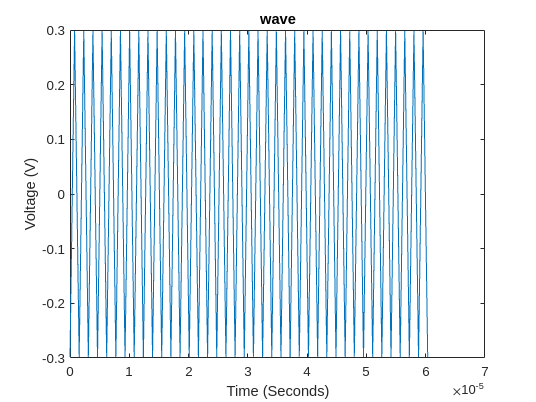

% Create plot of wave and wave
h = plot(wave(:,1),wave(:,2),"DisplayName","wave");

% Add xlabel, ylabel, title, and legend
xlabel("Time (Seconds)")
ylabel("Voltage (V)")
title("wave")

## Extract Signal Information

Fs = 1 / (wave(2,1) - wave(1,1));
L = length(wave);

## FFT

% Compute the Fourier transform of the signal.

Y = fft(wave(:,2));

% Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
P2 = abs(Y/L);
temp = P2(1:L/2+1);

P1(2:end-1) = 2*temp(2:end-1);

% Define the frequency domain f and plot the single-sided amplitude spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.
f = Fs*(0:(L/2))/L;
[M, I] = max(P1);
f1 = f(I);

## Plot the Spectrum

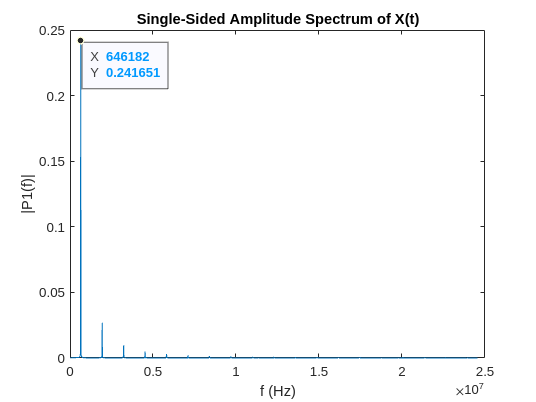

plot(f,P1) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")